Two-wheeled robot model 

load('model/kinematics/Transfer_functions.mat');

disp(beta)

$$\frac{\mathrm{Cm}\,R\,s^{2}\,\left(\mathrm{Jr}+\mathrm{Mr}\,R^{2}+\mathrm{Mt}\,R^{2}+\mathrm{Mt}\,R\,l\right)}{R\,s\,\left(\mathrm{Mt}\,l^{2}\,s^{2}-\mathrm{Mt}\,g\,l+\mathrm{Jt}\,s^{2}\right)\,\left(b_{\mathrm{attr}}+\mathrm{Jr}\,s+\mathrm{Mr}\,R^{2}\,s+\mathrm{Mt}\,R^{2}\,s\right)+\mathrm{Mt}\,R^{2}\,l\,s^{3}\,\left(b_{\mathrm{attr}}-\mathrm{Mt}\,R\,l\,s\right)}$$

disp(x)

$$\begin{array}{l} -\frac{\mathrm{Cm}\,R^{2}\,\sigma_{1}+\mathrm{Cm}\,\mathrm{Mt}\,R^{3}\,l\,s^{2}}{R\,s\,\sigma_{1}\,\left(b_{\mathrm{attr}}+\mathrm{Jr}\,s+\mathrm{Mr}\,R^{2}\,s+\mathrm{Mt}\,R^{2}\,s\right)+\mathrm{Mt}\,R^{2}\,l\,s^{2}\,\left(b_{\mathrm{attr}}\,s-\mathrm{Mt}\,R\,l\,s^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=s^{2}\,\left(\mathrm{Mt}\,l^{2}+\mathrm{Jt}\right)-\mathrm{Mt}\,g\,l \end{array}$$

We rearrange the coefficients in a vector form

den = [R*(Mt*l^2+Jt)*(Jr+Mr*R^2+Mt*R^2) - Mt^2*R^3*l^2, R*b_attr*(Mt*l^2+Jt) + Mt*R^2*l*b_attr, -R*Mt*g*l*(Jr+Mr*R^2+Mt*R^2), -R*Mt*g*l*b_attr, 0];

num_beta = [R*(Jr+Mr*R^2+Mt*R^2+Mt*R*l), 0, 0];

num_x = -[R^2*(Mt*l^2+Jt)+Mt*R^3*l, 0, -Mt*g*l*R^2];


A symbolic analysis of such transfer functions is very complex, hence we choose some reasonable values for the system parameters in order to get a more useful perspective of the problem

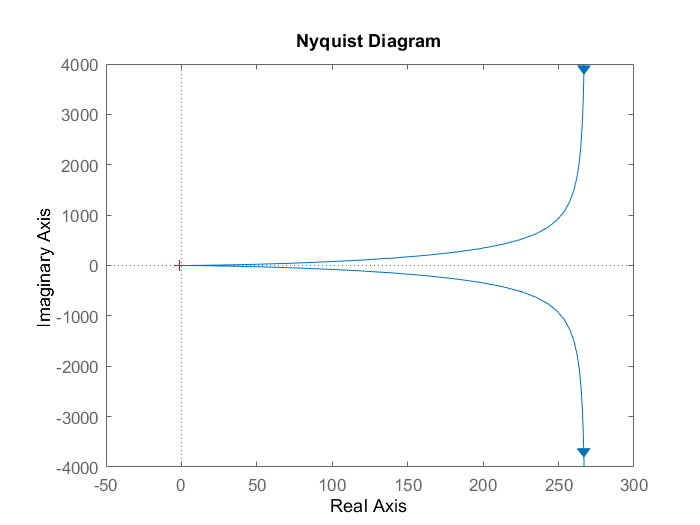


pi = 3.14;
b = 0.003;

num_beta = subs(num_beta, R, 0.1); % 10 cm radius for the wheels
num_beta = subs(num_beta, b_attr, b);   % ideal case with no friction between moving parts
num_beta = subs(num_beta, Mr, 2*pi*10^2*1*1.5*10^(-3));  % two wooden wheels with 10 cm radius and 1 cm large (we consider rotor inertia as negligible and gear ratio of 1)
num_beta = subs(num_beta, Jr, 0.5*2*pi*10^2*1*1.5*10^(-3)*0.1^2); 
num_beta = subs(num_beta, Mt, 1);   % 1 kg is a round up estimate
num_beta = subs(num_beta, l, 0.05);
num_beta = subs(num_beta, Jt, 0.5*1*(0.05^2)/2); 
num_beta = subs(num_beta, g, 9.81);

num_x = subs(num_x, R, 0.1); % 10 cm radius for the wheels
num_x = subs(num_x, b_attr, b);   % ideal case with no friction between moving parts
num_x = subs(num_x, Mr, 2*pi*10^2*1*1.5*10^(-3));  % two wooden wheels with 10 cm radius and 1 cm large (we consider rotor inertia as negligible and gear ratio of 1)
num_x = subs(num_x, Jr, 0.5*2*pi*10^2*1*1.5*10^(-3)*0.1^2); 
num_x = subs(num_x, Mt, 1);   % 1 kg is a round up estimate
num_x = subs(num_x, l, 0.05);
num_x = subs(num_x, Jt, 0.5*1*(0.05^2)/2); 
num_x = subs(num_x, g, 9.81);

den = subs(den, R, 0.1); % 10 cm radius for the wheels
den = subs(den, b_attr, b);   % ideal case with no friction between moving parts
den = subs(den, Mr, 2*pi*10^2*1*1.5*10^(-3));  % two wooden wheels with 10 cm radius and 1 cm large (we consider rotor inertia as negligible and gear ratio of 1)
den = subs(den, Jr, 0.5*2*pi*10^2*1*1.5*10^(-3)*0.1^2); 
den = subs(den, Mt, 1);   % 1 kg is a round up estimate
den = subs(den, l, 0.05);
den = subs(den, Jt, 0.5*1*(0.05^2)/2); 
den = subs(den, g, 9.81);

num_beta = double(num_beta);
num_x = double(num_x);
den = double(den);
Beta = tf(double(num_beta), double(den));
X = tf(double(num_x), double(den));
total = tf(double(num_beta+num_x), double(den));

%nyquist(Beta);
%nyquist(X);
nyquist(total);

disp(zero(total));

   0.0000 + 1.3161i
   0.0000 - 1.3161i



disp(pole(total));

         0
  -15.5056
   15.1463
   -0.1243



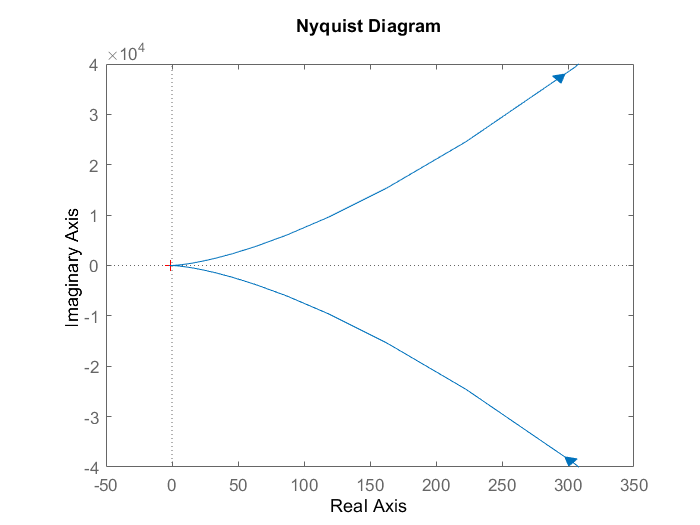


p = pole(total);

controller = tf([1, -p(2)], [1,0]) * tf([1, -p(4)], [1,0]);
loop = controller * total;
nyquist(loop);

disp(zero(loop));

 -15.5056 + 0.0000i
   0.0000 + 1.3161i
   0.0000 - 1.3161i
  -0.1243 + 0.0000i



disp(pole(loop));

         0
         0
         0
  -15.5056
   15.1463
   -0.1243

